Problem 4. 1D Hubbard model

First, construct MPO.

function Hs = Hubbard_MPO(L, U, t)
    c0 = [0,1,0,0; 0,0,0,0; 0,0,0,-1; 0,0,0,0];    % up-spin annihilation operator
    c1 = [0,0,1,0; 0,0,0,1; 0,0,0,0; 0,0,0,0];     % down-spin annihilation operator
    n0 = diag([0,1,0,1]);
    n1 = diag([0,0,1,1]);
    z = diag([1,-1,-1,1]);
    id = eye(4);

    Hs = cell(1,L);

    for i = 1:L
        W = zeros(4,4,6,6);

        W(:, :, 1, 1) = id;
        W(:, :, 2, 1) = c0' * z;
        W(:, :, 3, 1) = c1' * z;
        W(:, :, 4, 1) = z * c0;
        W(:, :, 5, 1) = z * c1;
        W(:, :, 6, 1) = 0.5 * U * (2*n0*n1 -n0-n1+id);
        W(:, :, 6, 2) = t*c0;
        W(:, :, 6, 3) = t*c1;
        W(:, :, 6, 4) = t*c0';
        W(:, :, 6, 5) = t*c1';
        W(:, :, 6, 6) = id;

        Hs{i} = W;
    end

    Hs{1} = Hs{1}(:, :, end, :); %첫번째 Hamiltonian chain 3번 leg dummy로
    Hs{end} = Hs{end}(:, :, :, 1); %마지막 Hamiltonian chain 4번 leg dummy로
end

Then, set the parameters and the list of N_keep.

N_sweep = 5;
L = 40;
physical_dim = 4;
t = 1;
N_keep_list = 20:20:400;

Now, obtain the ground-state energy using DMRG(I implemented MPS by iterative diagonalization and 1 site update) for various values of N_keep. Furthermore, keep increasing N_keep until ground-state energy change is negligible. 

25-05-20 15:31:42 | Sweep #1 of 10 (right -> left) : Energy = -32.8091
25-05-20 15:31:42 | Sweep #2 of 10 (left -> right) : Energy = -32.88891
25-05-20 15:31:42 | Sweep #3 of 10 (right -> left) : Energy = -32.93687
25-05-20 15:31:42 | Sweep #4 of 10 (left -> right) : Energy = -32.99099
25-05-20 15:31:42 | Sweep #5 of 10 (right -> left) : Energy = -33.03199
25-05-20 15:31:42 | Sweep #6 of 10 (left -> right) : Energy = -33.05888
25-05-20 15:31:43 | Sweep #7 of 10 (right -> left) : Energy = -33.08131
25-05-20 15:31:43 | Sweep #8 of 10 (left -> right) : Energy = -33.1018
25-05-20 15:31:43 | Sweep #9 of 10 (right -> left) : Energy = -33.12161
25-05-20 15:31:43 | Sweep #10 of 10 (left -> right) : Energy = -33.13661


Nkeep value : 20, E0 : -3.313661e+01

25-05-20 15:31:44 | Sweep #1 of 10 (right -> left) : Energy = -33.18828
25-05-20 15:31:44 | Sweep #2 of 10 (left -> right) : Energy = -33.20728
25-05-20 15:31:44 | Sweep #3 of 10 (right -> left) : Energy = -33.20917
25-05-20 15:31:44 | Sweep #4 of 10 (left -> right) : Energy = -33.21008
25-05-20 15:31:45 | Sweep #5 of 10 (right -> left) : Energy = -33.21061
25-05-20 15:31:45 | Sweep #6 of 10 (left -> right) : Energy = -33.21106
25-05-20 15:31:45 | Sweep #7 of 10 (right -> left) : Energy = -33.21139
25-05-20 15:31:45 | Sweep #8 of 10 (left -> right) : Energy = -33.21156
25-05-20 15:31:46 | Sweep #9 of 10 (right -> left) : Energy = -33.21164
25-05-20 15:31:46 | Sweep #10 of 10 (left -> right) : Energy = -33.21168


Nkeep value : 40, E0 : -3.321168e+01

25-05-20 15:31:47 | Sweep #1 of 10 (right -> left) : Energy = -33.20599
25-05-20 15:31:47 | Sweep #2 of 10 (left -> right) : Energy = -33.21837
25-05-20 15:31:48 | Sweep #3 of 10 (right -> left) : Energy = -33.21877
25-05-20 15:31:48 | Sweep #4 of 10 (left -> right) : Energy = -33.21892
25-05-20 15:31:49 | Sweep #5 of 10 (right -> left) : Energy = -33.2191
25-05-20 15:31:49 | Sweep #6 of 10 (left -> right) : Energy = -33.21922
25-05-20 15:31:49 | Sweep #7 of 10 (right -> left) : Energy = -33.21938
25-05-20 15:31:50 | Sweep #8 of 10 (left -> right) : Energy = -33.21951
25-05-20 15:31:50 | Sweep #9 of 10 (right -> left) : Energy = -33.21964
25-05-20 15:31:51 | Sweep #10 of 10 (left -> right) : Energy = -33.21987


Nkeep value : 60, E0 : -3.321987e+01

25-05-20 15:31:53 | Sweep #1 of 10 (right -> left) : Energy = -33.20958
25-05-20 15:31:53 | Sweep #2 of 10 (left -> right) : Energy = -33.21977
25-05-20 15:31:54 | Sweep #3 of 10 (right -> left) : Energy = -33.22105
25-05-20 15:31:55 | Sweep #4 of 10 (left -> right) : Energy = -33.22218
25-05-20 15:31:56 | Sweep #5 of 10 (right -> left) : Energy = -33.22238
25-05-20 15:31:57 | Sweep #6 of 10 (left -> right) : Energy = -33.22244
25-05-20 15:31:58 | Sweep #7 of 10 (right -> left) : Energy = -33.2225
25-05-20 15:31:59 | Sweep #8 of 10 (left -> right) : Energy = -33.22259
25-05-20 15:32:00 | Sweep #9 of 10 (right -> left) : Energy = -33.22268
25-05-20 15:32:02 | Sweep #10 of 10 (left -> right) : Energy = -33.22275


Nkeep value : 80, E0 : -3.322275e+01

25-05-20 15:32:05 | Sweep #1 of 10 (right -> left) : Energy = -33.21078
25-05-20 15:32:06 | Sweep #2 of 10 (left -> right) : Energy = -33.22203
25-05-20 15:32:08 | Sweep #3 of 10 (right -> left) : Energy = -33.22285
25-05-20 15:32:09 | Sweep #4 of 10 (left -> right) : Energy = -33.22335
25-05-20 15:32:11 | Sweep #5 of 10 (right -> left) : Energy = -33.22352
25-05-20 15:32:12 | Sweep #6 of 10 (left -> right) : Energy = -33.22357
25-05-20 15:32:14 | Sweep #7 of 10 (right -> left) : Energy = -33.2236
25-05-20 15:32:15 | Sweep #8 of 10 (left -> right) : Energy = -33.22362
25-05-20 15:32:17 | Sweep #9 of 10 (right -> left) : Energy = -33.22363
25-05-20 15:32:19 | Sweep #10 of 10 (left -> right) : Energy = -33.22364


Nkeep value : 100, E0 : -3.322364e+01

25-05-20 15:32:24 | Sweep #1 of 10 (right -> left) : Energy = -33.21636
25-05-20 15:32:26 | Sweep #2 of 10 (left -> right) : Energy = -33.22315
25-05-20 15:32:29 | Sweep #3 of 10 (right -> left) : Energy = -33.22374
25-05-20 15:32:33 | Sweep #4 of 10 (left -> right) : Energy = -33.22383
25-05-20 15:32:36 | Sweep #5 of 10 (right -> left) : Energy = -33.22385
25-05-20 15:32:40 | Sweep #6 of 10 (left -> right) : Energy = -33.22385
25-05-20 15:32:43 | Sweep #7 of 10 (right -> left) : Energy = -33.22386
25-05-20 15:32:46 | Sweep #8 of 10 (left -> right) : Energy = -33.22386
25-05-20 15:32:50 | Sweep #9 of 10 (right -> left) : Energy = -33.22386
25-05-20 15:32:53 | Sweep #10 of 10 (left -> right) : Energy = -33.22386


Nkeep value : 120, E0 : -3.322386e+01

25-05-20 15:33:03 | Sweep #1 of 10 (right -> left) : Energy = -33.21754
25-05-20 15:33:07 | Sweep #2 of 10 (left -> right) : Energy = -33.22293
25-05-20 15:33:11 | Sweep #3 of 10 (right -> left) : Energy = -33.22365
25-05-20 15:33:14 | Sweep #4 of 10 (left -> right) : Energy = -33.22389
25-05-20 15:33:18 | Sweep #5 of 10 (right -> left) : Energy = -33.22392
25-05-20 15:33:22 | Sweep #6 of 10 (left -> right) : Energy = -33.22393
25-05-20 15:33:26 | Sweep #7 of 10 (right -> left) : Energy = -33.22393
25-05-20 15:33:29 | Sweep #8 of 10 (left -> right) : Energy = -33.22393
25-05-20 15:33:32 | Sweep #9 of 10 (right -> left) : Energy = -33.22393
25-05-20 15:33:37 | Sweep #10 of 10 (left -> right) : Energy = -33.22394


Nkeep value : 140, E0 : -3.322394e+01

25-05-20 15:33:50 | Sweep #1 of 10 (right -> left) : Energy = -33.21859
25-05-20 15:33:54 | Sweep #2 of 10 (left -> right) : Energy = -33.22337
25-05-20 15:34:00 | Sweep #3 of 10 (right -> left) : Energy = -33.22393
25-05-20 15:34:03 | Sweep #4 of 10 (left -> right) : Energy = -33.22397
25-05-20 15:34:06 | Sweep #5 of 10 (right -> left) : Energy = -33.22398
25-05-20 15:34:11 | Sweep #6 of 10 (left -> right) : Energy = -33.22398
25-05-20 15:34:15 | Sweep #7 of 10 (right -> left) : Energy = -33.22398
25-05-20 15:34:19 | Sweep #8 of 10 (left -> right) : Energy = -33.22398
25-05-20 15:34:24 | Sweep #9 of 10 (right -> left) : Energy = -33.22399
25-05-20 15:34:28 | Sweep #10 of 10 (left -> right) : Energy = -33.22399


Nkeep value : 160, E0 : -3.322399e+01

25-05-20 15:34:40 | Sweep #1 of 10 (right -> left) : Energy = -33.21951
25-05-20 15:34:45 | Sweep #2 of 10 (left -> right) : Energy = -33.22366
25-05-20 15:34:52 | Sweep #3 of 10 (right -> left) : Energy = -33.22398
25-05-20 15:34:59 | Sweep #4 of 10 (left -> right) : Energy = -33.224
25-05-20 15:35:05 | Sweep #5 of 10 (right -> left) : Energy = -33.224
25-05-20 15:35:12 | Sweep #6 of 10 (left -> right) : Energy = -33.22401
25-05-20 15:35:19 | Sweep #7 of 10 (right -> left) : Energy = -33.22401
25-05-20 15:35:26 | Sweep #8 of 10 (left -> right) : Energy = -33.22401
25-05-20 15:35:32 | Sweep #9 of 10 (right -> left) : Energy = -33.22401
25-05-20 15:35:38 | Sweep #10 of 10 (left -> right) : Energy = -33.22401


Nkeep value : 180, E0 : -3.322401e+01

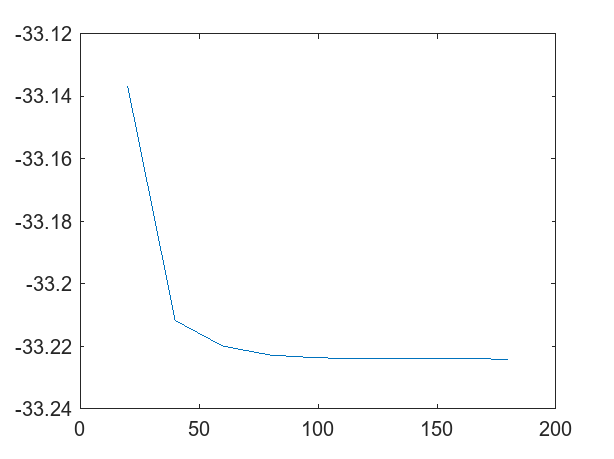

U = 2;
MPO = Hubbard_MPO(L, U, t);
E_G_list = zeros(length(N_keep_list));
threshold = 1e-6;

figure;
for i = 1 : length(N_keep_list)
    N_keep = N_keep_list(i);
    [M, E_G, E_list] = my_dmrg(MPO, N_keep, N_sweep, 0, 1, L, physical_dim);
    E_G_list(i) = E_G;
    fprintf('Nkeep value : %d, E0 : %d', N_keep, E_G);
    if i>1 && abs((E_G - E_G_prev)/E_G_prev) < threshold
        last_idx = i;
        break;
    end
    E_G_prev = E_G;
end

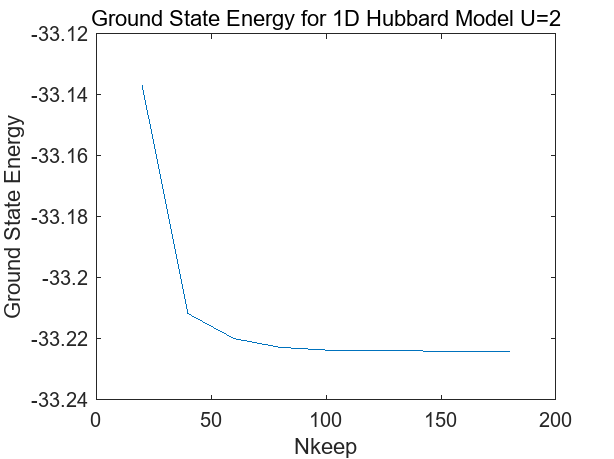

plot_list = E_G_list(1:last_idx);
plot_N_keep = N_keep_list(1:last_idx);
plot(plot_N_keep, plot_list);

title('Ground State Energy for 1D Hubbard Model U=2');
xlabel('Nkeep');
ylabel('Ground State Energy');


M0 = M; %to use the derived ground state

As N_keep was increased, the ground-state energy showed almost no change from N_keep = 180 onward, converging to a value of -33.22401.

Then, measure the double occupancy along the chain by computing it site by site, moving the orthogonality center through the chain using SVD.

%double occupancy

N = diag([0,0,0,1]) ; %double occupancy matrix
N_keep = N_keep_list(last_idx);
double_occupancy_list = zeros(1, L);

for i = L:-1:1 %from right to left, since M0 is left canonical
    X = contract(M0{i}, 3, [1, 2], conj(M0{i}), 3, [1, 2]);
    double_occupancy_list(i) = contract(X, 2, [1, 2], N, 2, [2, 1]);

    %move one site left
    if i > 1
        [U, S, M0{i}] = svdTr(M0{i}, 3, 1, N_keep, 0);
        US = contract(U, 2, 2, diag(S), 2, 1);
        M0{i-1} = contract(M0{i-1}, 3, 2, US, 2, 1, [1,3,2]);
    end
end
disp(double_occupancy_list);

    0.1393    0.1693    0.1688    0.1735    0.1726    0.1746    0.1739    0.1750    0.1745    0.1752    0.1748    0.1753    0.1750    0.1753    0.1751    0.1753    0.1752    0.1753    0.1753    0.1753    0.1753    0.1753    0.1753    0.1752    0.1753    0.1751    0.1753    0.1750    0.1753    0.1748    0.1752    0.1745    0.1750    0.1739    0.1746    0.1726    0.1735    0.1688    0.1693    0.1393



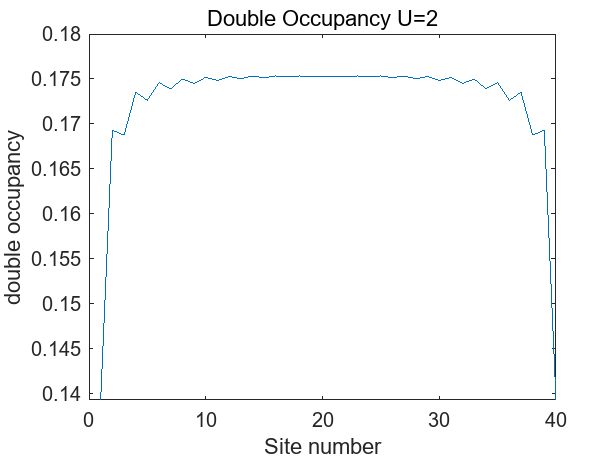

figure;
plot(1:L, double_occupancy_list);
title('Double Occupancy U=2');
xlabel('Site number');
ylabel('double occupancy');

The double occupancies were approximately between 0.17 and 0.175, except at the edge sites, where the values dropped to around 0.14.

b. Repeat for U=10!

This time, I used 2 site update because 1 site update did not work well.

U = 10;
MPO = Hubbard_MPO(L, U, t);
E_G_list = zeros(length(N_keep_list));
threshold = 1e-6;

figure;

for i = 1 : length(N_keep_list)
    N_keep = N_keep_list(i);
    [M, E_G, E_list] = my_dmrg(MPO, N_keep, N_sweep, 0, 2, L, physical_dim);
    E_G_list(i) = E_G;
    fprintf('Nkeep value : %d, E0 : %d', N_keep, E_G);
    if i>1 && abs((E_G - E_G_prev)/E_G_prev) < threshold
        last_idx = i;
        break;
    end
    E_G_prev = E_G;
end

25-05-20 15:40:26 | Sweep #1 of 10 (right -> left) : Energy = -9.883383
25-05-20 15:40:26 | Sweep #2 of 10 (left -> right) : Energy = -10.47715
25-05-20 15:40:26 | Sweep #3 of 10 (right -> left) : Energy = -10.51059
25-05-20 15:40:27 | Sweep #4 of 10 (left -> right) : Energy = -10.51552
25-05-20 15:40:27 | Sweep #5 of 10 (right -> left) : Energy = -10.5158
25-05-20 15:40:27 | Sweep #6 of 10 (left -> right) : Energy = -10.51589
25-05-20 15:40:28 | Sweep #7 of 10 (right -> left) : Energy = -10.51585
25-05-20 15:40:28 | Sweep #8 of 10 (left -> right) : Energy = -10.51589
25-05-20 15:40:28 | Sweep #9 of 10 (right -> left) : Energy = -10.51585
25-05-20 15:40:29 | Sweep #10 of 10 (left -> right) : Energy = -10.51589


Nkeep value : 20, E0 : -1.051589e+01

25-05-20 15:40:30 | Sweep #1 of 10 (right -> left) : Energy = -9.849963
25-05-20 15:40:31 | Sweep #2 of 10 (left -> right) : Energy = -10.47984
25-05-20 15:40:32 | Sweep #3 of 10 (right -> left) : Energy = -10.50947
25-05-20 15:40:33 | Sweep #4 of 10 (left -> right) : Energy = -10.51678
25-05-20 15:40:34 | Sweep #5 of 10 (right -> left) : Energy = -10.51795
25-05-20 15:40:35 | Sweep #6 of 10 (left -> right) : Energy = -10.51807
25-05-20 15:40:36 | Sweep #7 of 10 (right -> left) : Energy = -10.5181
25-05-20 15:40:38 | Sweep #8 of 10 (left -> right) : Energy = -10.5181
25-05-20 15:40:39 | Sweep #9 of 10 (right -> left) : Energy = -10.5181
25-05-20 15:40:40 | Sweep #10 of 10 (left -> right) : Energy = -10.5181


Nkeep value : 40, E0 : -1.051810e+01

25-05-20 15:40:42 | Sweep #1 of 10 (right -> left) : Energy = -9.954122
25-05-20 15:40:44 | Sweep #2 of 10 (left -> right) : Energy = -10.49911
25-05-20 15:40:46 | Sweep #3 of 10 (right -> left) : Energy = -10.51175
25-05-20 15:40:48 | Sweep #4 of 10 (left -> right) : Energy = -10.51582
25-05-20 15:40:50 | Sweep #5 of 10 (right -> left) : Energy = -10.51733
25-05-20 15:40:52 | Sweep #6 of 10 (left -> right) : Energy = -10.51808
25-05-20 15:40:55 | Sweep #7 of 10 (right -> left) : Energy = -10.51831
25-05-20 15:40:57 | Sweep #8 of 10 (left -> right) : Energy = -10.51834
25-05-20 15:40:59 | Sweep #9 of 10 (right -> left) : Energy = -10.51834
25-05-20 15:41:01 | Sweep #10 of 10 (left -> right) : Energy = -10.51834


Nkeep value : 60, E0 : -1.051834e+01

25-05-20 15:41:05 | Sweep #1 of 10 (right -> left) : Energy = -10.01947
25-05-20 15:41:10 | Sweep #2 of 10 (left -> right) : Energy = -10.48793
25-05-20 15:41:13 | Sweep #3 of 10 (right -> left) : Energy = -10.50476
25-05-20 15:41:16 | Sweep #4 of 10 (left -> right) : Energy = -10.51174
25-05-20 15:41:19 | Sweep #5 of 10 (right -> left) : Energy = -10.51502
25-05-20 15:41:22 | Sweep #6 of 10 (left -> right) : Energy = -10.51679
25-05-20 15:41:26 | Sweep #7 of 10 (right -> left) : Energy = -10.51768
25-05-20 15:41:29 | Sweep #8 of 10 (left -> right) : Energy = -10.51817
25-05-20 15:41:32 | Sweep #9 of 10 (right -> left) : Energy = -10.51832
25-05-20 15:41:35 | Sweep #10 of 10 (left -> right) : Energy = -10.51835


Nkeep value : 80, E0 : -1.051835e+01

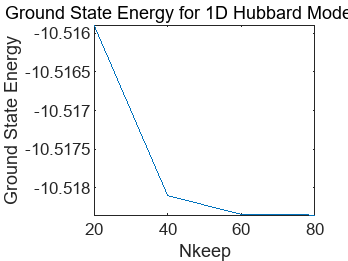

plot_list = E_G_list(1:last_idx);
plot_N_keep = N_keep_list(1:last_idx);
plot(plot_N_keep, plot_list);

title('Ground State Energy for 1D Hubbard Model U=10');
xlabel('Nkeep');
ylabel('Ground State Energy');


M1 = M; %to use the derived ground state

This time, as N_keep was increased, the ground-state energy showed almost no change from N_keep = 80 onward, converging to a value of -10.51835.

When 1 site update was implemented, the ground state energy value did not converge as N_keep grew.

%double occupancy
N = [diag([0,0,0,1])] ; %double occupancy matrix
N_keep = N_keep_list(last_idx);
double_occupancy_list = zeros(1, L);

for i = L:-1:1 %from right to left, since M0 is left canonical
    X = contract(M1{i}, 3, [1, 2], conj(M1{i}), 3, [1, 2]);
    double_occupancy_list(i) = contract(X, 2, [1, 2], N, 2, [2, 1]);

    %move one site left
    if i > 1
        [U, S, M1{i}] = svdTr(M1{i}, 3, 1, N_keep, 0);
        US = contract(U, 2, 2, diag(S), 2, 1);
        M1{i-1} = contract(M1{i-1}, 3, 2, US, 2, 1, [1,3,2]);
    end
end
disp(double_occupancy_list);

    0.0164    0.0256    0.0243    0.0251    0.0246    0.0250    0.0247    0.0249    0.0248    0.0249    0.0248    0.0249    0.0248    0.0249    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0248    0.0249    0.0248    0.0249    0.0248    0.0249    0.0248    0.0249    0.0247    0.0250    0.0246    0.0251    0.0243    0.0256    0.0164



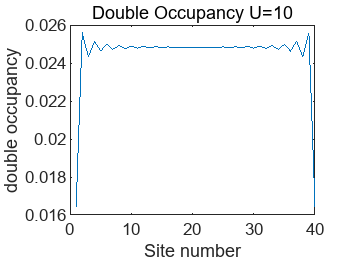

figure;
plot(1:L, double_occupancy_list);
title('Double Occupancy U=10');
xlabel('Site number');
ylabel('double occupancy');

This time, the double occupancy was much lower compared to the case of U = 2, with values around 0.025 except at the edges, where it was exactly 1/40. This suggests that a single pair of spin-up and spin-down electrons is uniformly distributed across all sites.